### Computational Methods in Ordinary Differential Equations

*Dr Jon Shiach, Department of Computing and Mathematics, Manchester Metropolitan University*

# Exercise Solutions

This page contains the solutions of the exercises on the pages for the topics shown below.

- Initial Value Problems

- Runge-Kutta Methods

- Implicit Runge-Kutta Methods

- Stability

- Boundary Value Problems

- Direct Methods for Solving Systems of Linear Equations

- Indirect Methods for Solving Systems of Linear Equations

## Initial Value Problems

1.     Using pen and a calculator and working to 4 decimal places, apply your Runge-Kutta method derived in question 3 to solve the following IVP using a step length of $h=0.4$


$$y\prime=ty, \qquad t\in[0,2], \qquad y(0)=1.$$


**        Solution:**


$$\begin{array}{ll}
y_0=1, & t_0=0, \\
y_1 = y_0 + ht_0y_0=1+0.4(0)(1) = 1, & t_1=t_0+h=0+0.4=0.4,\\
y_2 = y_1 + ht_1y_1 = 1 + 0.4(0.4)(1) = 1.16, & t_2=t_1+h=0.4+0.4=0.8, \\
y_3 = y_2 + ht_2y_2 = 1.16 + 0.4(0.8)(1.16) = 1.5312, & t_3 =t_2 + h = 0.8 + 0.4 =1.2,\\
y_4 = y_3 + ht_3y_3 = 1.5312 + 0.4(1.2)(1.5312) = 2.2662, & t_4 = t_3 + h=1.2+0.4 = 1.6, \\
y_5 = y_4 + ht_4y_4 = 2.2662 + 0.4(1.6)(2.2662) = 5.1724, & t_5 = t_4 + h = 1.6 + 0.4 = 2.
\end{array}$$


2.     Reproduce your solutions to question 1 using a MATLAB program.

**        Solution:**

clear

% Define ODE function
f = @(t, y) t .* y;

% Define IVP parameters
tspan = [ 0, 2 ];
y0 = 1;
h = 0.4;

% Solve IVP using the Euler method
[t, y] = euler(f, tspan, y0, h);

% Output solution table
table = ' t   Euler\n------------\n';
for n = 1 : length(t)
    table = [table , sprintf('%3.1f %7.4f\n', t(n), y(n,1))];
end
fprintf(table)

 t   Euler
------------
0.0  1.0000
0.4  1.0000
0.8  1.1600
1.2  1.5312
1.6  2.2662
2.0  3.7165


3.     The exam solution to the IVP in question 1 is $y=e^{t^2/2}$. Produce a plot of the Euler solution from question 2 against the exact solution.

        **Solution:**

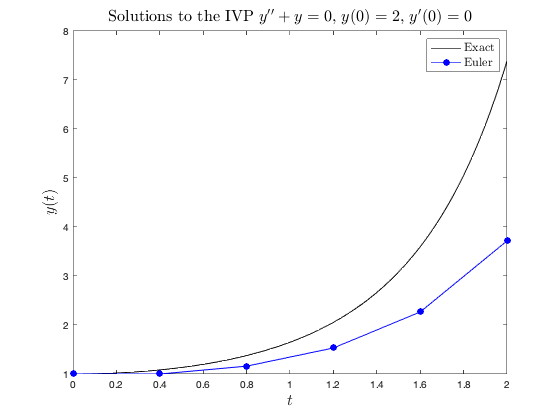

% Define exact solution
exact_sol = @(t) exp(t.^2 / 2);

% Plot solution
t1 = linspace(tspan(2), tspan(1), 100);
plot(t1, exact_sol(t1), 'k-')
hold on
plot(t, y(:, 1), 'bo-', 'MarkerFaceColor', 'b')
hold off

xlabel('$t$', 'fontsize', 16, 'Interpreter', 'latex')
ylabel('$y(t)$', 'FontSize', 16, 'Interpreter', 'latex')
title("Solutions to the IVP $y'' + y = 0$, $y(0)=2$, $y'(0)=0$", ...
    'FontSize', 16, 'Interpreter', 'latex')
leg = legend('Exact', 'Euler');
set(leg, 'Location', 'Northeast', 'FontSize', 12, 'Interpreter', 'latex')

## Runge-Kutta Methods

1.     Write the following Runge-Kutta method in a Butcher tableau.


$$y_{n+1} = y_n + \frac{h}{6}(k_1 + 4k_3 + k_4), \\
\quad k_1 = f(t_n, y_n), \\
\quad k_2 = f(t_n + \frac{1}{4}h, y_n + \frac{1}{4}hk_1), \\
\quad k_3 = f(t_n + \frac{1}{2}h, y_n + \frac{1}{2}hk_2), \\
\quad k_4 = f(t_n + h, y_n + h(k_1 - 2k_2 + 2k_3)).$$


**        Solution:**


$$\begin{array}{c|cccc}
0 & \\ 
\frac{1}{4} & \frac{1}{4} \\
\frac{1}{2} & 0 & \frac{1}{2} \\
1 & 1 & -2 & 2 \\ 
& \frac{1}{6} & 0 & \frac{2}{3} & \frac{1}{6}
\end{array}$$


2.     Write out the equations for the following Runge-Kutta method.


$$\begin{array}{c|cccc}
0 & \\
\frac{1}{4} & \frac{1}{4} \\
\frac{1}{2} & -\frac{1}{2} & 1 \\
1 & \frac{1}{4} & 0 & \frac{3}{4} \\
& 0 & \frac{4}{9} & \frac{1}{3} & \frac{2}{9}
\end{array}$$


**        Solution:**


$$y_{n+1} = y_n + \frac{h}{9}(4k_2 + 3k_3 + 2k_4), \\
\quad k_1 = f(t_n, y_n), \\
\quad k_2 = f(t_n+\frac{1}{4}h, y_n + \frac{1}{4}hk_1), \\
\quad k_3 = f(t_n + \frac{1}{2}h, y_n + h(-\frac{1}{2}k_1 + k_2)), \\
\quad k_4 = f(t_n + h, y_n + h(\frac{1}{4}(k_1 + 3k_3)).$$


3.     Derive an explicit second-order Runge-Kutta method such that $b_1 = \frac{1}{3}$.

**        Solution:**

clear

% Define symbolic variables
syms a21 b1 b2 c2
b1 = 1/3;

% Order conditions
eqn1 = b1 + b2 == 1;
eqn2 = b2 * c2 == 1/2;
eqn3 = a21 * b2 == 1/2;

% Solve system
[a21, b2, c2] = solve(eqn1, eqn2, eqn3);

% Output A, b and c arrays
for i = 1 : 1
    A = [ 0 , 0 ; a21, 0 ]
    b = [ b1 ; b2 ]
    c = [ 0 ; c2 ]
end

$$A = \left(\begin{array}{cc} 0 & 0\\ \frac{3}{4} & 0 \end{array}\right)$$

$$b = \left(\begin{array}{c} \frac{1}{3}\\ \frac{2}{3} \end{array}\right)$$

$$c = \left(\begin{array}{c} 0\\ \frac{3}{4} \end{array}\right)$$

4.     Derive an explicit fourth-order Runge-Kutta method such that $b_1=0$ and $c_2=\frac{1}{5}$.

        **Solution:**

clear 
% Initialise symbolic variables
syms a21 a31 a32 a41 a42 a43 b1 b2 b3 b4 c2 c3 c4
b1 = 0;
c2 = 1/5;

% Define order conditions
eqn1 = b1 + b2 + b3 + b4 == 1;
eqn2 = b2 * c2 + b3 * c3 + b4 * c4 == 1/2;
eqn3 = b2 * c2^2 + b3 * c3^2 + b4 * c4^2 == 1/3;
eqn4 = b2 * c2^3 + b3 * c3^3 + b4 * c4^3 == 1/4;
eqn5 = b3 * c3 * a32 * c2 + b4 * c4 * (a42 * c2 + a43 * c3) == 1/8;
eqn6 = b3 * a32 + b4 * a42 == b2 * (1 - c2);
eqn7 = b4 * a43 == b3 * (1 - c3);
eqn8 = 0 == b4 * (1 - c4);
eqn9 = c2 == a21;
eqn10 = c3 == a31 + a32;
eqn11 = c4 == a41 + a42 + a43;

% Solver order conditions
[a21, a31, a32, a41, a42, a43, b2, b3, b4, c3, c4] ...
    = solve(eqn1, eqn2, eqn3, eqn4, eqn5, eqn6, eqn7, eqn8, eqn9, eqn10, eqn11);

% Output A, b and c arrays
for i = 1 : 1
    A = [ 0, 0, 0, 0 ; a21, 0, 0, 0 ; a31, a32, 0, 0 ; a41, a42, a43, 0]
    b = [ b1 ; b2 ; b3 ; b4 ]
    c = [ 0 ; c2 ; c3 ; c4 ]
end

$$A = \left(\begin{array}{cccc} 0 & 0 & 0 & 0\\ \frac{1}{5} & 0 & 0 & 0\\ -\frac{31}{32} & \frac{55}{32} & 0 & 0\\ 9 & -\frac{120}{11} & \frac{32}{11} & 0 \end{array}\right)$$

$$b = \left(\begin{array}{c} 0\\ \frac{125}{264}\\ \frac{16}{33}\\ \frac{1}{24} \end{array}\right)$$

$$c = \left(\begin{array}{c} 0\\ \frac{1}{5}\\ \frac{3}{4}\\ 1 \end{array}\right)$$

5.     Using pen and a calculator and working to 4 decimal places, apply your Runge-Kutta method derived in question 3 to solve the following IVP using a step length of $h=0.4$


$$y\prime=ty, \qquad t\in[0, 2], \qquad y(0)=1.$$


**        Solution:**


$$k_1 = t_0y_0 = 0(1) = 0, \\
k_2 = (t_0+c_2h)(y_0 + a_{12}hk_1) = \left(0 + \frac{3}{4}(0.4)\right)\left(1 + \frac{3}{4}(0.4)(0)\right) = 0.3,\\
y_1 = y_0 + \frac{h}{3}(k_1 + 2k_2) = 1 + \frac{0.4}{3}(0 +0.3 ) = 1.08,\\
 t_1 = t_0 + h = 0 + 0.4 = 0.4, \\
\\
k_1 = t_1y_1 = (0.4)(1.08) = 0.432, \\
k_2 = (t_1 + c_2h)(y_1+a_{21}hk_1) = \left( 0.4 + \frac{3}{4}(0.4)\right)\left(1.08 + \frac{3}{4}(0.4)(0.432)\right) = 0.8467, \\
y_2 = y_1 + \frac{h}{3}(k_1 + 2k_2) = 1.08 + \frac{0.4}{3}(0.432 + 2(0.8467)) = 1.3634,\\
 t_2 = t_1 + h = 0.4 + 0.4 = 0.8, \\
\\
k_1 = t_2y_2 = 0.8(1.3634) = 1.0907, \\
k_2 = (t_2 + c_2h)(y_2 + a_{21}hk_1) = \left(0.8 + \frac{3}{4}(0.4)\right)\left(1.3634 + \frac{3}{4}(0.4)(1.0907)\right) = 1.8597, \\
y_3 = y_2 + \frac{h}{3}(k_1 + 2k_2) = 1.3634 + \frac{0.4}{3}(1.0907 + 2(1.8597)) = 2.0047, \\
 t_3 = t_2 + h = 0.8 + 0.4 = 1.2, \\
\\
k_1 = t_3y_3 = 1.2(2.0047) = 2.4057, \\
k_2 = (t_3 + c_2h)(y_3 + a_{21}hk_1) = \left(1.2 + \frac{3}{4}(0.4)\right)\left(2.0047 + \frac{3}{4}(0.4)(2.4057)\right) = 4.0897, \\
y_4 = y_3 + \frac{h}{3}(k_1 + 2k_2) = 2.0047 + \frac{0.4}{3}(2.4057 + 2(4.0897)) = 3.4161, \\
 t_4 =t_3 + h = 1.2 + 0.4 = 1.6, \\
\\
k_1 = t_4y_4 = 1.6(3.4161), \\
k_2 = (t_4 + c_2h)(y_4 + a_{21}hk_1) = \left(1.6 + \frac{3}{4}(0.4)\right)\left(3.4161 + \frac{3}{4}(0.4)(3.4161)\right) = 9.6060, \\
y_5 = y_4 + \frac{h}{3}(k_1 + 2k_2) = 3.4161 + \frac{0.4}{3}(5.4647 + 2(9.6060)) = 6.7064, \\
t_5 = t_4 + h = 1.6 + 0.4 = 2.$$


6.     Repeat question 5 using the RK4 method (the RK4 method is derived in example 4).

**        Solution:**


$$k_1 = t_0y_0 = 0(1) = 0, \\
k_2 = (t_0 + c_2h)(y_0 + a_{21}hk_1) = \left(0 + \frac{1}{2}(0.4)\right)\left(1 + \frac{1}{2}(0.4)(0)\right) = 0.2, \\
k_3 = (t_0 + c_3h)(y_0 + h(a_{31}k_1 + a_{32}k_2)) = \left(0 + \frac{1}{2}(0.4)\right)\left(1 + \frac{1}{2}(0.4)(0.2)\right)=0.2080, \\
k_4 = (t_0 + c_4h)(y_0 + h(a_{41}k_1 + a_{42}k_2 + a_{43}k_3)) = \left(0 + 0.4)\right)\left(1 + 0.4(0.2080)\right) = 0.4333, \\
y_1 = y_0 + \frac{h}{6}(k_1 + 2k_2 + 2k_3 + k_4) = 1 + \frac{0.4}{6}(0 + 2(0.2) + 2(0.2080) + 0.4333) = 1.0833, \\
t_1 = t_0 + h = 0 + 0.4 = 0.4,\\
\\
k_1 = t_1y_1 = 0.4(1.0833) = 0.4333, \\
k_2 = (t_1 + c_2h)(y_1 + a_{21}hk_1) = \left(0.4 + \frac{1}{2}(0.4)\right)\left(1.0833 + \frac{1}{2}(0.4)(0.4333)\right) = 0.7020, \\
k_3 = (t_1 + c_3h)(y_1 + h(a_{31}k_1 + a_{32}k_2)) = \left(0.4 + \frac{1}{2}(0.4)\right)\left(1.0833 + \frac{1}{2}(0.4)(0.7020)\right)=0.7342, \\
k_4 = (t_1 + c_4h)(y_1 + h(a_{41}k_1 + a_{42}k_2 + a_{43}k_3)) = \left(0.4 + 0.4\right)\left(1.0833 + 0.4(0.7342)\right) = 1.1016, \\
y_2 = y_1 + \frac{h}{6}(k_1 + 2k_2 + 2k_3 + k_4) = 1.0833 + \frac{0.4}{6}(04333 + 2(0.7020) + 2(0.7342) + 1.1016) = 1.3771, \\
t_2 = t_1 + h = 0.4 + 0.4 = 0.8,\\
\\
k_1 = t_2y_2 = 0.8(1.3771) = 1.1017, \\
k_2 = (t_2 + c_2h)(y_2 + a_{21}hk_1) = \left(0.8 + \frac{1}{2}(0.4)\right)\left(1.3771 + \frac{1}{2}(0.4)(1.1017)\right) = 1.5974, \\
k_3 = (t_2 + c_3h)(y_2 + h(a_{31}k_1 + a_{32}k_2)) = \left(0.8 + \frac{1}{2}(0.4)\right)\left(1.3771 + \frac{1}{2}(0.4)(1.5974)\right)=1.6966, \\
k_4 = (t_2 + c_4h)(y_2 + h(a_{41}k_1 + a_{42}k_2 + a_{43}k_3)) = \left(0.8 + 0.4\right)\left(1.3771 + 0.4(1.6966)\right) = 2.4669, \\
y_3 = y_2 + \frac{h}{6}(k_1 + 2k_2 + 2k_3 + k_4) = 1.3771 + \frac{0.4}{6}(1.1017+ 2(1.5974) + 2(1.6966) + 2.4669) = 2.0542, \\
t_3 = t_2 + h = 0.8 + 0.4 = 1.2,\\
\\
k_1 = t_3y_3 = 1.2(2.0542) = 2.4561, \\
k_2 = (t_3 + c_2h)(y_3 + a_{21}hk_1) = \left(1.2 + \frac{1}{2}(0.4)\right)\left(2.0542 + \frac{1}{2}(0.4)(2.4651)\right) = 3.5661, \\
k_3 = (t_3 + c_3h)(y_3 + h(a_{31}k_1 + a_{32}k_2)) = \left(1.2 + \frac{1}{2}(0.4)\right)\left(2.0542 + \frac{1}{2}(0.4)(3.5661)\right)=3.8744, \\
k_4 = (t_3 + c_4h)(y_3 + h(a_{41}k_1 + a_{42}k_2 + a_{43}k_3)) = \left(1.2 + 0.4\right)\left(2.0542 + 0.4(3.8744)\right) = 5.7664, \\
y_4 = y_3 + \frac{h}{6}(k_1 + 2k_2 + 2k_3 + k_4) = 2.0542 + \frac{0.4}{6}(2.4561 + 2(3.5661) + 2(3.8744) + 5.7664) = 3.5950, \\
t_4 = t_3 + h = 1.2 + 0.4 = 1.6,\\
\\
k_1 = t_4y_4 = 1.6(3.5950) = 5.7521, \\
k_2 = (t_4 + c_2h)(y_4 + a_{21}hk_1) = \left(1.6 + \frac{1}{2}(0.4)\right)\left(3.5950 + \frac{1}{2}(0.4)(5.7521)\right) = 8.5418, \\
k_3 = (t_4 + c_3h)(y_4 + h(a_{31}k_1 + a_{32}k_2)) = \left(1.2 + \frac{1}{2}(0.4)\right)\left(3.5950 + \frac{1}{2}(0.4)(8.5418)\right)= 9.5461, \\
k_4 = (t_4 + c_4h)(y_4 + h(a_{41}k_1 + a_{42}k_2 + a_{43}k_3)) = \left(1.2 + 0.4\right)\left(3.5950 + 0.4(9.5461)\right) = 14.8270, \\
y_5 = y_4 + \frac{h}{6}(k_1 + 2k_2 + 2k_3 + k_4) = 3.5950 + \frac{0.4}{6}(5.7521 + 2(8.5418) + 2(9.5461) + 14.8270) = 7.3787, \\
t_5 = t_4 + h = 1.6 + 0.4 = 2.$$


7.     Repeat question 5 using MATLAB to perform the calculations. The exact solution to this IVP is $y=e^{t^2/2}$. Produce a table comparing the numerical and exact solutions. Produce a plot of the numerical solutions and exact solutions on the same set of axes. 

**        Solution:**

clear

% Define ODE function
f = @(t, y) t .* y;

% Define exact solution
exact = @(t) exp(t.^2 / 2);

% Define IVP parameters
tspan = [ 0, 2 ];
y0 = 1;
h = 0.4;

% Invoke RK2 method to solve IVP
nsteps = floor((tspan(2) - tspan(1)) / h);
t = zeros(nsteps + 1, 1);
y = zeros(nsteps + 1, 1);
t(1) = tspan(1);
y(1) = y0;

% Loop through steps
for n = 1 : nsteps
    k1 = f(t(n), y(n));
    k2 = f(t(n) + 0.75 * h, y(n) + 0.75 * h * k1);
    y(n+1) = y(n) + h / 3 * (k1 + 2 * k2);
    t(n+1) = t(n) + h;
end

% Output solution table
table = sprintf(' t     RK2     Exact \n--------------------\n');
for n = 1 : length(t)
    table = [table , sprintf('%3.2f %7.4f %7.4f\n', t(n), y(n), exact(t(n)))];
end
fprintf(table)

 t     RK2     Exact 
--------------------
0.00  1.0000  1.0000
0.40  1.0800  1.0833
0.80  1.3634  1.3771
1.20  2.0047  2.0544
1.60  3.4161  3.5966
2.00  6.7064  7.3891


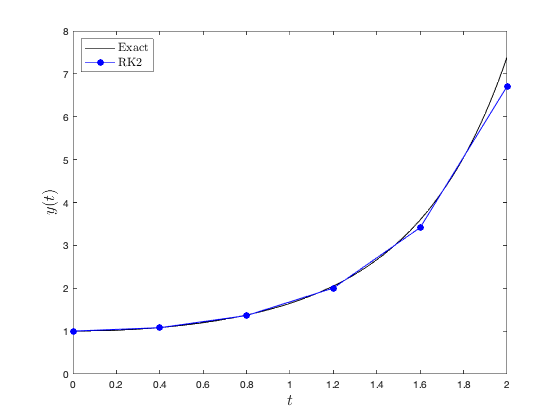


% Plot solutions
t1 = linspace(tspan(1), tspan(2), 100);
plot(t1, exact(t1), 'k-')
hold on
plot(t, y, 'bo-', 'markerfacecolor', 'blue')
hold off

xlabel('$t$', 'fontsize', 16, 'Interpreter', 'latex')
ylabel('$y(t)$', 'FontSize', 16, 'Interpreter', 'latex')
leg = legend('Exact', 'RK2');
set(leg, 'Location', 'Northwest', 'FontSize', 12, 'Interpreter', 'latex')
axis([tspan, 0, 8])

## Implicit Runge-Kutta Methods

1.    Show that the Radau IA derived in example 3 is a third-order method.

        **Solution:**

        The Radau IA method is 


$$A = \pmatrix{0 & 0 \cr \frac{1}{3} & \frac{1}{3}}, \qquad \mathbf{b} = \pmatrix{\frac{1}{4} \cr \frac{3}{4}}, \qquad \mathbf{c} = \pmatrix{0 \cr \frac{2}{3}}.$$


        Check the $B(k)$ condition


$$\begin{array}{lll}
j = 1: & LHS = b_1 + b_2 = \frac{1}{4} + \frac{3}{4} = 1, & RHS = 1, \\
j = 2 : & LHS = b_1c_1 + b_2c_2 = \frac{1}{4}(0) + \frac{3}{4}\left(\frac{2}{3}\right) = \frac{1}{2}, & RHS = \frac{1}{2}, \\
j = 3 : & LHS = b_1c_1^2 + b_2c_2^2 = \frac{1}{4}(0)^2 + \frac{3}{4}\left(\frac{2}{3}\right)^2 = \frac{1}{3}, & RHS = \frac{1}{3}, \\
j = 4 : & LHS = b_1c_1^3 + b_2c_2^3 = \frac{1}{4}(0)^2 + \frac{3}{4}\left(\frac{2}{3}\right)^3 = \frac{2}{9}, & RHS = \frac{1}{4}.
\end{array}$$


        So this IRK method can be upto order $k=3$. Since $\lfloor 3/2 \rfloor = 1$ check the the $C(1)$ condition:


$$\begin{array}{lll}
j = 1: & LHS = a_{11} + a_{12} = 0 + 0 = 0, & RHS = c_1 = 0, \\
j = 2: & LHS = a_{21} + a_{22} = \frac{1}{3} + \frac{1}{3} = \frac{2}{3}, & RHS = \frac{2}{3}.
\end{array}$$


        So the $C(1)$ condition is satisfied. Check the $D(1)$ condition


$$\begin{array}{lll}
i = 1: & LHS = a_{11}b_1 + a_{21}b_2 = 0\left(\frac{1}{4}\right)+\frac{1}{3}\left(\frac{3}{4}\right) = \frac{1}{4}, & RHS = b_1 (1 - c_1) = \frac{1}{4}(1 - 0) = \frac{1}{4}, \\
i = 2: & LHS = a_{12}b_1 + a_{22}b_2 = 0\left(\frac{1}{4}\right) + \frac{1}{3}\left(\frac{3}{4}\right) = \frac{1}{4}, & RHS= b_2(1 - c_2) = \frac{3}{4}\left(1 - \frac{2}{3}\right) = \frac{1}{4}.
\end{array}$$


        Since the $C(3)$, $C(1)$ and $D(1)$ conditions are satisfied then this is a third-order IRK method.

2.    Determine the order of the following IRK method


$$\begin{array}{c|ccc}
0 & 0 & 0 \\
\frac{1}{2} & \frac{1}{4} & \frac{1}{4} & 0 \\
1 & 0 & 1 & 0 \\
& \frac{1}{6} & \frac{2}{3} & \frac{1}{6}
\end{array}$$


        **Solution:**

        Check the $B(k)$ condition:


$$\begin{array}{lll}
j = 1: & LHS = b_1 + b_2 + b_3 = \frac{1}{6} + \frac{2}{3} + \frac{1}{6} = 1, & RHS = 1, \\
j = 2: & LHS = b_1c_1 + b_2c_2 + b_3c_3 = \frac{1}{6}(0) + \frac{2}{3}\left(\frac{1}{2}\right) + \frac{1}{6}(1) = \frac{1}{2}, & RHS = \frac{1}{2}, \\
j = 3: & LHS = b_1c_1^2 + b_2c_2^2 + b_3c_3^2 = \frac{1}{6}(0)^2 + \frac{2}{3}\left(\frac{1}{2}\right)^2 + \frac{1}{6}(1)^2 = \frac{1}{3}, & RHS = \frac{1}{3} , \\
j = 4: & LHS = b_1c_1^3 + b_2c_2^3 + b_3c_3^3 = \frac{1}{6}(0)^3 + \frac{2}{3}\left(\frac{1}{2}\right)^3 + \frac{1}{6}(1)^3 = \frac{1}{4}, & RHS = \frac{1}{4},  \\
j = 5: & LHS = b_1c_1^4 + b_2c_2^4 + b_3c_3^4 = \frac{1}{6}(0)^3 + \frac{2}{3}\left(\frac{1}{2}\right)^4 + \frac{1}{6}(1)^4 = \frac{5}{24}, & RHS = \frac{1}{5}.
\end{array}$$


        So this IRK method can be upto order 4. Check the $C(2)$ condition:


$$\begin{array}{llll}
\ell = 1, & i = 1: & LHS = a_{11} + a_{12} + a_{13} = 0 + 0 + 0 = 0, & RHS = 0, \\
& i = 2 : & LHS = a_{21} + a_{22} + a_{32} = \frac{1}{4} + \frac{1}{4} + 0 = \frac{1}{2}, & RHS =  \frac{1}{2}, \\
& i = 3 : & LHS = a_{31} + a_{32} + a_{33} = 0 + 1 + 0 = 1, & RHS = 1, \\
\ell = 2, & i = 1 : & LHS = a_{11}c_1 + a_{12}c_2 + a_{13}c_3 = 0(0) + 0\left(\frac{1}{2}\right) + 0(1) = 0, & RHS = \frac{1}{2}c_1^2 = \frac{1}{2}(0)^2 = 0, \\
& i = 2: & LHS = a_{21}c_1 + a_{22}c_2 + a_{23}c_3 = \frac{1}{4}(0) + \frac{1}{4}\left(\frac{1}{2}\right) + 0(1) = \frac{1}{8}, & RHS = \frac{1}{2}c_2^2 = \frac{1}{2}\left(\frac{1}{2}\right)^2 = \frac{1}{8}, \\
& i = 3: & LHS = a_{31}c_1 + a_{32}c_2 + a_{33}c_3 = 0(0) + 1\left(\frac{1}{2}\right) + 0(1) = \frac{1}{2}, & RHS = \frac{1}{2}(c_3)^2 = \frac{1}{3}(1)^2 = \frac{1}{3}.
\end{array}$$


        Since the $C(k)$ condition is only satisfied upto $k=1$ then this IRK method can be upto order 3. Check the $D(1)$ condition:


$$\begin{array}{lll}
j = 1: & LHS = b_1a_{11} + b_2a_{21} + b_3a_{31} = \frac{1}{6}(0) + \frac{2}{3}\left(\frac{1}{4}\right) + \frac{1}{6}(0) = \frac{1}{6}, & RHS = b_1(1 - c_1) = \frac{1}{6}(1 -0) = \frac{1}{6}, \\
j = 2 : & LHS = b_1a_{12} + b_2a_{22} + b_3a_{32} = \frac{1}{6}(0) + \frac{2}{3}\left(\frac{1}{4}\right) + \frac{1}{6}(1) = \frac{1}{3}, & RHS = b_2 (1 - c_2) = \frac{2}{3}\left(1 - \frac{1}{2}\right) = \frac{1}{3}, \\
j = 3: & LHS = b_1a_{13} + b_2a_{23} + b_3a_{33} = \frac{1}{6}(0) + \frac{1}{2}(0) + 1(0) = 0, & RHS = b_3(1 - c_3) = \frac{1}{6}(1 - 1) = 0.
\end{array}$$


        So the $D(1)$ condition is satisfied so this IRK method is a third-order method.

3.    Derive a third-order Radau IIA method.

        **Solution:**

        An $s$-stage Radau method has order $k=2s-1$ so $k=2$. Let $c_2=1$ and choose $c_1$ to be the root of $P_2(t) - P_1(t) = 3t^2 - 4t + 1$ which is $c_1 =  \frac{1}{3}$.

        The $B(2)$ and $C(1)$ order conditions are


$$\qquad \,\,b_1 + b_2 = 1, \\
\,\,\,\,\,\,b_1c_1 + b_2c_2 = \frac{1}{2},\\
\quad \,\,\,\,\,a_{11} + a_{12} = c_1, \\
\qquad \!\!a_{21} + a_{22} = c_2, \\
a_{11}b_1 + a_{12}b_2 = \frac{1}{2}c_1^2, \\
a_{21} b_1 + a_{22} b_2 = \frac{1}{2}c_2^2.$$


clear

% Define symbolic variables
syms t a11 a12 a21 a22 b1 b2 c1 c2
c2 = 1;

c = solve(3 * t^2 - 4 * t + 1 == 0);
c1 = c(1);

% Define order conditions
eqn1 = b1 + b2 == 1;
eqn2 = b1 * c1 + b2 * c2 == 1/2;
eqn3 = a11 + a12 == c1;
eqn4 = a21 + a22 == c2;
eqn5 = a11 * c1 + a12 * c2 == 1/2 * c1^2;
eqn6 = a21 * c1 + a22 * c2 == 1/2 * c2^2;

% Solve system
[a11, a12, a21, a22, b1, b2] = solve(eqn1, eqn2, eqn3, eqn4, eqn5, eqn6);

% Output A, b and c arrays
for i = 1 : 1
    A = [ a11, a12 ; a21, a22 ]
    b = [ b1 ; b2 ]
    c = [ c1 ; c2 ]
end

$$A = \left(\begin{array}{cc} \frac{5}{12} & -\frac{1}{12}\\ \frac{3}{4} & \frac{1}{4} \end{array}\right)$$

$$b = \left(\begin{array}{c} \frac{3}{4}\\ \frac{1}{4} \end{array}\right)$$

$$c = \left(\begin{array}{c} \frac{1}{3}\\ 1 \end{array}\right)$$

4.    Derive a two-stage second-order SDIRK method with $c_1=\frac{1}{4}$.

        **Solution:**

        Since $c_1=\frac{1}{4}$ then $a_{11} =a_{22} = \frac{1}{4}$ and $a_{12}=0$ then the $B(2)$ and $D(1)$ order conditions are


$$\quad \,\,\,\,\,\,b_1 + b_2 = 1, \\
\,b_1c_1 + b_2c_2 = \frac{1}{2}, \\
\qquad \!\!a_{21} + c_1 = c_2, \\
b_1c_1 + b_2a_{21} = b_1(1 - c_1), \\
\qquad \quad \,b_2c_1 = b_2(1-c_2).$$


clear

% Define symbolic variables
syms a21 b1 b2 c1 c2
c1 = 1/4;

% Define order conditions
eqn1 = b1 + b2 == 1;
eqn2 = b1 * c1 + b2 * c2 == 1/2;
eqn3 = a21 + c1 == c2;
eqn4 = b1 * c1 + b2 * a21 == b1 * (1 - c1);
eqn5 = b2 * c1 == b2 * (1 - c2);

% Solve system
[a21, b1, b2, c2] = solve(eqn1, eqn2, eqn3, eqn4, eqn5);

% Output A, b and c arrays
for i = 1 : 1
    A = [ c1, 0 ; a21, c1 ]
    b = [ b1 ; b2 ]
    c = [ c1 ; c2 ]
end

$$A = \left(\begin{array}{cc} \frac{1}{4} & 0\\ \frac{1}{2} & \frac{1}{4} \end{array}\right)$$

$$b = \left(\begin{array}{c} \frac{1}{2}\\ \frac{1}{2} \end{array}\right)$$

$$c = \left(\begin{array}{c} \frac{1}{4}\\ \frac{3}{4} \end{array}\right)$$

5.   Using pen and a calculator and working to 4 decimal places, calculate the first step of your IRK method derived in question 4 to solve the following IVP using a step length of $h=0.4$


$$y\prime=ty, \qquad t\in[0, 2], \qquad y(0)=1.$$


        **Solution:**

        $y_0=1$, $t_0=0$ and using the Jacobi method with starting values of $Y^0=(1, 1)^T$ 

        
$$Y^1 = y_0 + hAf(t_0+\mathbf{c}h, Y^0) = 1 + 0.4\pmatrix{\frac{1}{4} & 0 \cr \frac{1}{2} & \frac{1}{4}} \pmatrix{ \left(0 + \frac{1}{4}(0.4)\right)(1) \cr \left(0 + \frac{3}{4}(0.4)\right)(1)} = \pmatrix{1.01 \cr 1.05}, \\
Y^2 = y_0 + hAf(t_0+\mathbf{c}h, Y^1) = 1 + 0.4\pmatrix{\frac{1}{4} & 0 \cr \frac{1}{2} & \frac{1}{4}} \pmatrix{\left( 0 + \frac{1}{4}(0.4)\right)(1.01) \cr \left(0 + \frac{3}{4}(0.4)\right)(1.05)} = \pmatrix{1.0101 \cr 1.0517}, \\
Y^3 =  y_0 + hAf(t_0+\mathbf{c}h, Y^2) = 1 + 0.4\pmatrix{\frac{1}{4} & 0 \cr \frac{1}{2} & \frac{1}{4}} \pmatrix{\left( 0 + \frac{1}{4}(0.4)\right)(1.0101) \cr \left(0 + \frac{3}{4}(0.4)\right)(1.0517)} = \pmatrix{1.0101 \cr 1.0518}, \\
Y^4 =  y_0 + hAf(t_0+\mathbf{c}h, Y^3) = 1 + 0.4\pmatrix{\frac{1}{4} & 0 \cr \frac{1}{2} & \frac{1}{4}} \pmatrix{\left( 0 + \frac{1}{4}(0.4)\right)(1.0101) \cr \left(0 + \frac{3}{4}(0.4)\right)(1.0518)} = \pmatrix{1.0101 \cr 1.0518}.$$


        Calculate $y_1$


$$\,\,y_1 = y_0 + h(b_1f(t_0+c_1h, Y_1) + b_2f(t_0+c_2h, Y_2)) \\
\quad = 1 + \frac{0.4}{2}\left(\left(0 + \frac{1}{4}(0.4)\right)(1.0101) + \left(0 +\frac{3}{4}(0.4)\right)(1.0518)\right) = 1.0833.$$


6.    The exact solution to this IVP is $y=e^{t^2/2}$. Using MATLAB produce a table comparing the numerical and exact solutions and plot the numerical solutions and exact solutions on the same set of axes

clear

% Define ODE function
f = @(t, y) t .* y;

% Define exact solution
exact_sol = @(t) exp(t.^2 / 2);

% Define IVP parameters
tspan = [ 0, 2 ];
y0 = 1;
h = 0.4;

% Define IRK method
A = [ 1/4, 0 ; 1/2, 1/4 ];
b = [ 1/2 ; 1/2 ];
c = [ 1/4 ; 3/4 ];

% Invoke IRK method to solve IVP
[t, y] = irk(f, tspan, y0, h, A, b, c);

% Output solution table
table = sprintf(' t     IRK    Exact \n--------------------\n');
for n = 1 : length(t)
    table = [table , sprintf('%3.2f %7.4f %7.4f\n', t(n), y(n), exact_sol(t(n)))];
end
fprintf(table)

 t     IRK    Exact 
--------------------
0.00  1.0000  1.0000
0.40  1.0833  1.0833
0.80  1.3776  1.3771
1.20  2.0580  2.0544
1.60  3.6164  3.5966
2.00  7.4893  7.3891


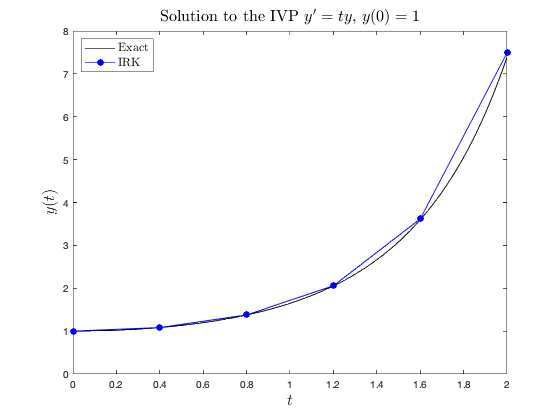

% Plot solutions
t1 = linspace(tspan(1), tspan(2), 100);
plot(t1, exact_sol(t1), 'k-')
hold on
plot(t, y, 'bo-', 'markerfacecolor', 'blue')
hold off

axis([ tspan, 0, 8 ])
xlabel('$t$', 'fontsize', 16, 'Interpreter', 'latex')
ylabel('$y(t)$', 'FontSize', 16, 'Interpreter', 'latex')
title("Solution to the IVP $y'=ty$, $y(0)=1$", 'FontSize', 16, 'Interpreter', 'latex')
leg = legend('Exact', 'IRK');
set(leg, 'Location', 'Northwest', 'FontSize', 12, 'Interpreter', 'latex')

## Stability

1.    Determine the stability function of the following Runge-Kutta method


$$\begin{array}{c|ccccc}
0 \\
\frac{1}{4} & \frac{1}{4} \\
\frac{1}{2} & \frac{1}{2} & 0 \\
\frac{3}{4} & 0 & \frac{1}{2} & \frac{1}{4} \\
0 & 0 & \frac{1}{6} & -\frac{1}{3} & \frac{1}{6} \\
& -1 & \frac{2}{3} & -\frac{1}{3} & \frac{2}{3} & 1
\end{array}$$


clear

% Define RK method
A = [ 0, 0, 0, 0, 0 ; 1/4, 0, 0, 0, 0 ; 1/2, 0, 0, 0, 0 ; 0, 1/2, 1/4, 0, 0 ; 0, 1/6, -1/3, 1/6, 0 ];
b = [ -1 ; 2/3 ; -1/3 ; 2/3 ; 1 ];
c = [ 0 ; 1/4 ; 1/2 ; 3/4 ; 0 ];
s = 5;
e = ones(s, 1);

% Determine stability function
R = 'R(z) = 1';
for k = 1 : s
    coeff = b' * A^(k-1) * e;
    R = [ R, sprintf(' + %s z^%1i', strtrim(rats(coeff)), k) ];
end
fprintf(R)

R(z) = 1 + 1 z^1 + 1/2 z^2 + 1/6 z^3 + 1/24 z^4 + 0 z^5

2.     Determine the stability function of the following Runge-Kutta method. Is this an A-stable method?


$$\begin{array}{c|cc}
\frac{1}{4} & \frac{7}{24} & -\frac{1}{24} \\
\frac{3}{4} & \frac{13}{24} & \frac{5}{24} \\ 
& \frac{1}{2} & \frac{1}{2}
\end{array}$$


clear

% Define RK method
A = [ 7/24, -1/24 ; 13/24, 5/24 ];
b = [ 1/2 ; 1/2 ];
I = eye(2);

% Calculate P(z) and Q(z) polynomials
syms z
P = det(I - z * (A - b));
Q = det(I - z * A);

% Calculate roots of Q
Qroot = solve(Q == 0);

% Calculate E(y)
syms y
Pp = det(I + 1i * y * (A - b));
Pm = det(I - 1i * y * (A - b));
Qp = det(I + 1i * y * A);
Qm = det(I - 1i * y * A);
E = expand(Qp * Qm - Pp * Pm);

% Output P(z), Q(z), roots of Q(z) and E(y)
fprintf('P(z) = %s\nQ(z) = %s\nThe roots of Q are %s and %s\nE(y) = %s', ...
    P, Q, Qroot(1), Qroot(2), E)

P(z) = z/2 + z^2/12 + 1
Q(z) = z^2/12 - z/2 + 1
The roots of Q are 3 - 3^(1/2)*1i and 3^(1/2)*1i + 3
E(y) = 0

        The stability function is 

$R(z) = \frac{1 + \frac{1}{2}z + \frac{1}{12}z^2}{1 - \frac{1}{2}z + \frac{1}{12}z^2}$.

        Since the roots of $Q(z)$ have positive real parts and $E(y)=0$ then this is an A-stable method.

3.     Plot the region of absolute stability for the following Runge-Kutta method.


$$\begin{array}{c|cc}
\frac{1}{3} & \frac{1}{3} & 0 \\
1 & 1 & 0 \\
& \frac{3}{4} & \frac{1}{4}
\end{array}$$


clear

% Define RK method
A = [ 1/3 , 0 ; 1, 0 ];
b = [ 3/4 , 0 ; 0, 1/4 ];
I = eye(2);

% Calculate P(z) and Q(z) polynomials
syms z
P = det(I - z * (A - b));
Q = det(I - z * A);

% Output P(z), Q(z), roots of Q(z) and E(y)
fprintf('P(z) = %s\nQ(z) = %s', expand(P), Q)

P(z) = (2*z)/3 + (5*z^2)/48 + 1
Q(z) = 1 - z/3

        The stability function for this IRK method is


$$R(z) = \frac{1 + \frac{2}{3}z + \frac{5}{48}z^2}{1 - \frac{1}{3}z}.$$


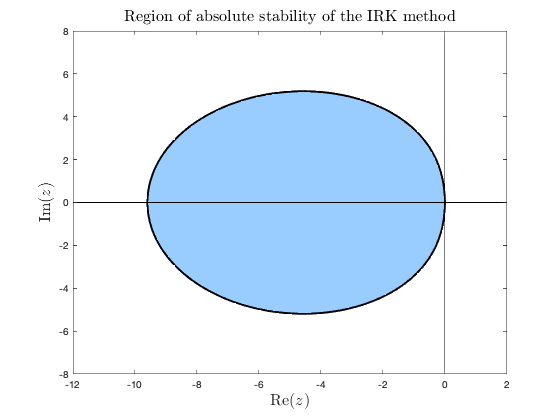

% Generate z values
x = linspace(-10, 10, 100);
y = linspace(-10, 10, 100);
[X, Y] = meshgrid(x, y);
Z = X + Y * 1i;

% Define the stability function for the backwards Euler method
R = (1 + 2/3 * Z + 5/48 * Z .^ 2) ./ (1 - 1/3 * Z);

% Plot the region of absolute stability
contourf(X, Y, abs(R), [0 1], 'linewidth', 2)
hold on
plot([ -12, 10 ], [ 0, 0 ], 'k-')
plot([ 0, 0 ], [ -10, 10 ], 'k-')
hold off

xlabel('$\mathrm{Re}(z)$', 'FontSize', 16, 'Interpreter', 'latex')
ylabel('$\mathrm{Im}(z)$', 'FontSize', 16, 'Interpreter', 'latex')
title('Region of absolute stability of the IRK method', ...
    'FontSize', 16, 'Interpreter', 'latex')
axis([ -12, 2, -8, 8 ])
colormap([ 153, 204, 255 ; 255, 255, 255 ] / 255)

4.    Determine the stability function of the following Runge-Kutta method. What is the order of the method?


$$\begin{array}{c|ccccc}
0 \\
\frac{2}{7} & \frac{2}{7} \\
\frac{4}{7} & -\frac{8}{35} & \frac{4}{5} \\
\frac{6}{7} & \frac{29}{42} & -\frac{2}{3} & \frac{5}{6} \\
1 & \frac{1}{6} & \frac{1}{6} & \frac{5}{12} & \frac{1}{4} \\
& \frac{11}{96} & \frac{7}{24} & \frac{35}{96} & \frac{7}{48} & \frac{1}{12}
\end{array}$$


clear

% Define RK method
A = [ 0, 0, 0, 0, 0 ; 2/7, 0, 0, 0, 0 ; -8/35, 4/5, 0, 0, 0 ; 29/42, -2/3, 5/6, 0, 0 ; 1/6, 1/6, 5/12, 1/4, 0 ];
b = [ 11/96 ; 7/24 ; 35/96 ; 7/48 ; 1/12 ];
s = 5;
e = ones(s, 1);

% Determine stability function
R = 'R(z) = 1';
for k = 1 : s
    coeff = b' * A^(k-1) * e;
    R = [ R, sprintf(' + %s z^%1i', strtrim(rats(coeff)), k) ];
end
fprintf(R)

R(z) = 1 + 1 z^1 + 1/2 z^2 + 1/6 z^3 + 1/24 z^4 + 1/252 z^5

        $R(z)$ agrees to the series expansion of $e^z$ upto the fourth-order term therefore this is a fourth-order method.

5.     Calculate the stiffness ratio for the following system of ODEs. 


$$y_1\prime = -80.6y_1 + 119.4y_2, \\ 
y_2\prime = 79.6y_1 - 120.4y_2.$$


        What are the maximum step lengths that the Euler method is stable for solving each equation?

% Define coefficient matrix
A = [ -80.6, 119.4 ; 79.6, -120.4 ];

% Calculate eigenvalues
lambda = eig(A);

% Calculate stiffness ratio
S = max(abs(real(lambda))) / min(abs(real(lambda)));

for i = 1 : 1
fprintf('The stiffness ratio is S=%1.1f', S)
fprintf('The step lengths of the Euler method are h = %1.4f and h = %1.4f', -2/lambda(1), -2/lambda(2))
end

The stiffness ratio is S=200.0

The step lengths of the Euler method are h = 2.0000 and h = 0.0100

## Boundary Value Problems

1.    Determine which of the following BVPs have a unique solution:

        (a)    $y\prime\prime=-\frac{4}{t}y\prime + \frac{2}{t^2}y - \frac{2\ln(t)}{t^3}, \qquad t \in [1, 2], \qquad y(1) = \frac{1}{2}, \qquad y(2) = \ln(2)$;

        **Solution:**

        $p(t)=-\frac{4}{t}$, $q(t)=\frac{2}{t^2}$ and $r(t)=-\frac{2\ln(t)}{t^3}$ are all continuous over the domain and $q(t)>0$ for all $t\in [1, 2]$ so the solution to this BVP is unique.

        (b)    $y\prime\prime = e^t + y\cos(t) - (t+1)y\prime, \qquad t \in [0, 2], \qquad y(0)=1, \qquad y(2) = \ln(3)$;

        **Solution:**

        $p(t)=-(t+1)$, $q(t)=\cos(t)$ and $r(t)=e^t$. This BVP does not have a solution since $q(t)<0$ for $t\in\left[ \frac{\pi}{2}, 2\right]$.

        (c)    $y\prime\prime = (t^3 + 5)y + \sin(t), \qquad t \in [0, 1], \qquad y(0)=0, \qquad y(1) = 1$;

        **Solution:**

        $p(t)=t^3+5$, $q(t)=0$ and $\sin(t)$. This BVP does not have a unique solution since $q(t)\not >0$.

        (d)    $y\prime\prime = (5y + \sin (3t))e^t, \qquad t\in [0, 1], \qquad y(0)=0, \qquad y(1)=0$.

        **Solution:**

        $p(t)=0$, $q(t)=5e^t$, $r(t)=e^t \sin(3t)$ are all continuous over the domain and $q(t)>0$ for all $t\in [0, 1]$ so the solution to this BVP is unique.

2.     Consider the following BVP


$$y\prime\prime = 2t, \qquad t \in [0, 2], \qquad y(0)=1, \qquad y(2)=3.$$


        Using a pen and calculator, calculate the Euler method solutions using a step length of $h=0.5$ for each of the following guess values:

        (a)    $s=1$;

        **Solution:**

        This ODE can be written as the following system


$$\begin{array}{ll}
y_1\prime = y_2, \qquad & y_1(0)=1\\ 
y_2\prime = 2t, & y_2(0)= s.
\end{array}$$


        Let $\mathbf{y} = \pmatrix{y_1 \cr y_2}$ and $F(t, \mathbf{y})=\pmatrix{y_2 \cr 2t}$ and using $s = 1$ $\textbf{y}_0 = \pmatrix{1\cr1}$:


$$\begin{array}{ll}
\mathbf{y}_1 = \mathbf{y}_0 + hF(t, \mathbf{y}_0) = \pmatrix{1 \cr 1} + 0.5\pmatrix{1 \cr 2(0)} = \pmatrix{1.5\cr 1}, & 
t_1 = t_0 + h = 0 + 0.5 = 0.5, \\
\mathbf{y}_2 = \mathbf{y}_1 + hF(t, \mathbf{y}_1) = \pmatrix{1.5\cr 1}+ 0.5 \pmatrix{1 \cr 2(0.5)} = \pmatrix{2\cr 1.5}, &
t_2 = t_1 + h = 0.5 + 0.5 = 1, \\
\mathbf{y}_3 = \mathbf{y}_2 + hF(t, \mathbf{y}_2) = \pmatrix{2 \cr 1.5} + 0.5\pmatrix{1.5 \cr 2(1)} = \pmatrix{2.75 \cr 2.5}, &
t_3 = t_2 + h = 1 + 0.5 = 1.5, \\
\mathbf{y}_4 = \mathbf{y}_3 + h F(t, \mathbf{y}_3) = \pmatrix{2.75 \cr 2.5} + 0.5\pmatrix{2.5 \cr 2(1.5)} = \pmatrix{4 \cr 4}, &
t_4 = t_3 + h = 1.5 + 0.5 = 2.
\end{array}
$$


        (b)    $s=-1$.

        **Solution:**

        Using $s=-1$, $\mathbf{y}_0 = \pmatrix{1 \cr -1}$:


$$\begin{array}{ll}
\mathbf{y}_1 = \pmatrix{1 \cr -1} + 0.5\pmatrix{-1 \cr 2(0)} = \pmatrix{0.5\cr -1}, & 
t_1 = 0 + 0.5 = 0.5, \\
\mathbf{y}_2 = \pmatrix{0.5\cr -1}+ 0.5 \pmatrix{-1 \cr 2(0.5)} = \pmatrix{0\cr -0.5}, &
t_2 = 0.5 + 0.5 = 1, \\
\mathbf{y}_3 = \pmatrix{0 \cr -0.5} + 0.5\pmatrix{-0.5 \cr 2(1)} = \pmatrix{-0.25 \cr 0.5}, &
t_3 = 1 + 0.5 = 1.5, \\
\mathbf{y}_4 = \pmatrix{-0.25 \cr 0.5} + 0.5\pmatrix{0.5 \cr 2(1.5)} = \pmatrix{0 \cr 2}, &
t_4 = 1.5 + 0.5 = 2.
\end{array}
$$


3.    Use the secant method to calculate the next value of s for your solutions to the BVP in question 2 and hence calculate the Euler method using this new guess value.

        **Solution:**

        
$$s_2 = s_0 - F(s_1) \frac{s_1 - s_0}{ F(s_1) - F(s_0)}=1 - (3-0)\frac{-1 - 1}{(3-0) - (3 - 4)} = 0.5.$$


        Using $s=0.5$, $\mathbf{y}_0 = \pmatrix{1 \cr 0.5}$:


$$\begin{array}{ll}
\mathbf{y}_1 = \pmatrix{1 \cr 0.5} + 0.5\pmatrix{0.5 \cr 2(0)} = \pmatrix{1.25 \cr 0.5}, & 
t_1 = 0 + 0.5 = 0.5, \\
\mathbf{y}_2 = \pmatrix{1.25 \cr 0.5}+ 0.5 \pmatrix{0.5 \cr 2(0.5)} = \pmatrix{1.5 \cr 1}, &
t_2 = 0.5 + 0.5 = 1, \\
\mathbf{y}_3 = \pmatrix{1.5 \cr 1} + 0.5\pmatrix{1 \cr 2(1)} = \pmatrix{2 \cr 2}, &
t_3 = 1 + 0.5 = 1.5, \\
\mathbf{y}_4 = \pmatrix{2 \cr 2} + 0.5\pmatrix{2 \cr 2(1.5)} = \pmatrix{3 \cr 3}, &
t_4 = 1.5 + 0.5 = 2.
\end{array}
$$


4.    Using a pen and calculator, calculate the solution of the BVP in question 2 using the finite-difference method with a step length $h=0.5$.

**Solution:**

        Using $y\prime\prime = \frac{y_{i-1} - 2y_i + y_{i+1}}{h^2}$


$$\frac{y_{i-1} - 2y_i + y_{i+1}}{h^2} = 2t_i \\
y_{i-1} - 2y_i + y_{i+1} = 2h^2t_i.$$


        and for $i=1$ and $i=N-1$


$$-2y_1 + y_2 = 2h^2t_1 - y_0, \\ y_{N-2} - 2y_N = 2h^2t_i - y_{N}.$$


        Therefore we have the linear system


$$\pmatrix{-2 & 1 \cr 1 & -2 & 1 \cr & \ddots & \ddots & \ddots \cr & & 1 & -2 & 1 \cr & & & 1 & -2}
\pmatrix{y_1 \cr y_2 \cr \vdots \cr y_{N-2} \cr y_{N-1}} = 
\pmatrix{2h^2t_1 - y_0 \cr 2h^2t_2 \cr \vdots \cr 2h^2t_{N-2} \cr 2h^2t_{N-1} - y_N}.$$


        Since $y_0=1$, $y_N=3$, $h=0.5$ so $\mathbf{t} = (0, 0.5, 1.0, 1.5, 2)$ and the linear system is

$\pmatrix{-2 & 1& 0 \cr 1 & -2 & 1 \cr 0 & 1 & -2}\pmatrix{ y_1 \cr y_2 \cr y_3} = \pmatrix{-0.99 \cr 0.02 \cr -2.97}$.

        The inverse of the coefficient matrix can be determined using the adjoint-determinant formula


$$A{-1} = \frac{1}{\det(A)}\text{adj}(A), \\
\det(A) = -2 \left| \matrix{-2 & 1 \cr 1 & -2}\right|-\left| \matrix{1 & 1 \cr 0 & -2}\right| = -6 + 2 = -4, \\
\text{adj}(A) = \pmatrix{3 & 2 & 1 \cr 2 & 4 & 2 \cr 1 & 2 & 3}^T = \pmatrix{3 & 2 & 1 \cr 2 & 4 & 2 \cr 1 & 2 & 3}, \\
\therefore A^{-1} = -\frac{1}{4} \pmatrix{3 & 2 & 1 \cr 2 & 4 & 2 \cr 1 & 2 & 3}.$$


        Using $\mathbf{y} = A^{-1}\mathbf{b}$ then


$$\pmatrix{ y_1 \cr y_2 \cr y_3} = -\frac{1}{4}\pmatrix{3 & 2 & 1 \cr 2 & 4 & 2 \cr 1 & 3 & 3} 
\pmatrix{ -0.99 \cr 0.02 \cr -2.97} =
\pmatrix{ 1.475 \cr 1.96 \cr 2.465}.$$


        So the solution is $\mathbf{y} = (1, 1.475, 1.96, 2.465, 3)^T$. 

5.    Write a MATLAB program to repeat questions 3 and 4 using a step length of $h=0.1$. The exact solution to this BVP is $y=\frac{1}{3}t^3 - \frac{1}{3}t+1$. Produce a plot of the numerical solution and exact solution on the same set of axes.

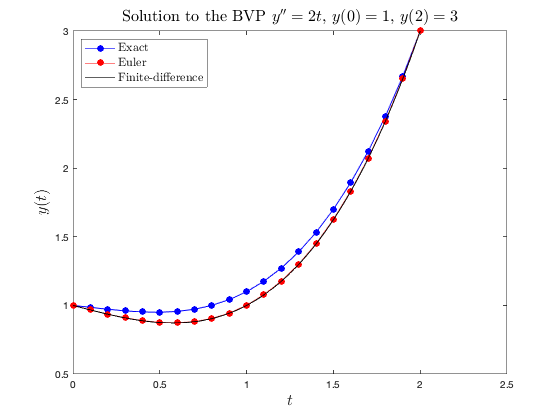

clear

% Define ODE function
f = @(t, y) [ y(2) , 2 * t];

% Define exact solution
exact_sol = @(t) 1/3 * t .^ 3 - 1/3 * t + 1;

% Define BVP parameters
tspan = [ 0, 2 ];
bvals = [ 1, 3 ];
h = 0.1;

% ----------------------------------------------------------------------
% Shooting method solution
s0 = 1;
s1 = -1;

% Solve system using s = 1
[t, y] = euler(f, tspan, [ 1, s0 ], h);
F0 = bvals(2) - y(end, 1);

% Solve system using s = -1
[t, y] = euler(f, tspan, [ 1, s1 ], h);
F1 = bvals(2) - y(end, 1);

% Calculate next guess value using the Secant method
s2 = s1 - F1 * (s1 - s0) / (F1 - F0);

% Solve system using new guess value
[t, y] = euler(f, tspan, [ 1, s2 ], h);

% ----------------------------------------------------------------------
% Finite difference method solution
% Initialise solution array
N = floor((tspan(2) - tspan(1)) / h) + 1;
y1 = zeros(N, 1);
y1(1) = bvals(1);
y1(N) = bvals(2);

% Define linear system
A = diag(ones(N-3, 1), -1) + -2 * diag(ones(N-2, 1)) + diag(ones(N-3, 1), 1);
d = 2 * h ^ 2 * t(2:N-1);
d(1) = d(1) - y(1);
d(N-2) = d(N-2) - y(N);

% Solve linear system
y1(2:N-1) = inv(A) * d;

% Plot solutions
t1 = linspace(tspan(1), tspan(2), 100);
plot(t, y(:, 1), 'bo-', 'markerfacecolor', 'blue')
hold on
plot(t, y1, 'ro-', 'MarkerFaceColor', 'red')
plot(t1, exact_sol(t1), 'k-')
hold off

xlabel('$t$', 'fontsize', 16, 'Interpreter', 'latex')
ylabel('$y(t)$', 'FontSize', 16, 'Interpreter', 'latex')
title("Solution to the BVP $y''=2t$, $y(0)=1$, $y(2)=3$", 'FontSize', 16, 'Interpreter', 'latex')
leg = legend('Exact', 'Euler', 'Finite-difference');
set(leg, 'Location', 'Northwest', 'FontSize', 12, 'Interpreter', 'latex')

## Direct Methods for Solving Systems of Linear Equations

1.     Solve the following systems of linear equations using LU decomposition with a pen and calculator.

        (a)    $2x_1 + 3x_2 - x_3 = 4, \\
4x_1 + 9x_2 - x_3 = 18, \\
\qquad 3x_2 + 2x_3 = 11.$         

**        Solution: **$$L = \pmatrix{ 1 & 0 & 0 \cr 2 & 1 & 0 \cr 0 & 1 & 1 },
U = \pmatrix{ 2 & 3 & -1 \cr 0 & 3 & 1 \cr 0 & 0 & 1},
\mathbf{x} = \pmatrix{ -2 \cr 3 \cr 1 }$

        (b)    $3x_1 + 9x_2 + 5x_3 = 20, \\
 \,\,\,\,   x_1 + 2x_2 + 2x_3 = 3, \\
    2x_1 + 4x_2 + 5x_3 = 4.$        

        **Solution:    **$$L = \pmatrix{ 1 & 0 & 0 \cr 1/3 & 1 & 0 \cr 2/3 & 2 & 1 },
U = \pmatrix{ 3 & 9 & 5 \cr 0 & -1 & 1/3 \cr 0 & 0 & 1 },
\mathbf{x} = \pmatrix{ 1 \cr 3 \cr -2 }.$$

        (c)    $\qquad \,\,\,x_1 + 3x_3 + 2x_4 = 21, \\
    3x_1 - 2x_2 + 5x_3 + x_4 = 28, \\
    4x_1 - x_2 - 2x_3 - 3x_4 = -12, \\
   \qquad \qquad \,\,\, 2x_2 + 3x_4 = 13.$

        (d)      $\,\,\,\,\,\,x_1 + 5x_2 + 2x_3 + 2x_4 = -10, \\
\quad\,\,\,\,    -2x_1 - 4x_2 + 2x_3 = 10, \\
\quad\,\,    3x_1 + x_2 - 2x_3 - x_4 = -2, \\
    -3x_1 - 3x_2 + 4x_3 - x_4 = 4.$

        **Solution:**

2.     Solve the systems from question 1 using LU decomposition with partial pivotting using a pen and calculator.

      (a)    $2x_1 + 3x_2 - x_3 = 4, \\
4x_1 + 9x_2 - x_3 = 18, \\
\qquad 3x_2 + 2x_3 = 11.$         

**        Solution:     **$P = \pmatrix{ 0 & 1 & 0 \cr 1 & 0 & 0 \cr 0 & 0 & 1 }, 
L = \pmatrix{ 1 & 0 & 0 \cr 1/2 & 1 & 0 \cr 0 & -2 & 1 },
U = \pmatrix{ 4 & 9 & -1 \cr 0 & -3/2 & -1/2 \cr 0 & 0 & 1 }, 
\mathbf{x} = \pmatrix{ -2 \cr 3 \cr 1 }.$

      (b)    $3x_1 + 9x_2 + 5x_3 = 20, \\
 \,\,\,\,   x_1 + 2x_2 + 2x_3 = 3, \\
    2x_1 + 4x_2 + 5x_3 = 4.$

**        Solution:** $P = \pmatrix{ 1 & 0 & 0 \cr 0 & 0 & 1 \cr 0 & 1 & 0 }, 
L = \pmatrix{ 1 & 0 & 0 \cr 2/3 & 1 & 0 \cr 1/3 & 1/2 & 1 },
U = \pmatrix{ 3 & 9 & 5 \cr 0 & -2 & 5/3 \cr 0 & 0 & -1/2 }, 
\mathbf{x} = \pmatrix{ 1 \cr 3 \cr -2 }.$

        (c)    $\qquad \,\,\,x_1 + 3x_3 + 2x_4 = 21, \\
    3x_1 - 2x_2 + 5x_3 + x_4 = 28, \\
    4x_1 - x_2 - 2x_3 - 3x_4 = -12, \\
   \qquad \qquad \,\,\, 2x_2 + 3x_4 = 13.$

        **Solution:**    $P = \pmatrix{ 0 & 0 & 1 & 0 \cr 0 & 1 & 0 & 0 \cr 1 & 0 & 0 & 0 \cr 0 & 0 & 0 & 1 }, 
$$L = \pmatrix{ 1 & 0 & 0 & 0 \cr 3/4 & 1 & 0 & 0 \cr 1/3 & -1/5 & 1 & 0 \cr 0 & -8/5 & 13/6 & 1 },$$U = \pmatrix{ 4 & -1 & -2 & -3 \cr 0 & -5/4 & 13/2 & 7/4 \cr 0 & 0 & 24/5 & 17/4 \cr 0 & 0 & 0 & 5/6 },$$\mathbf{x} = \pmatrix{ 2 \cr -1 \cr 3 \cr 5 }.$

        (d)      $\,\,\,\,\,\,x_1 + 5x_2 + 2x_3 + 2x_4 = -10, \\
\quad\,\,\,\,    -2x_1 - 4x_2 + 2x_3 = 10, \\
\quad\,\,    3x_1 + x_2 - 2x_3 - x_4 = -2, \\
    -3x_1 - 3x_2 + 4x_3 - x_4 = 4.$

        **Solution:    **$P = \pmatrix{ 0 & 0 & 1 & 0 \cr 0 & 1 & 0 & 0 \cr 0 & 0 & 0 & 1 \cr 1 & 0 & 0 & 0 }$, $L = \pmatrix{ 1 & 0 & 0 & 0 \cr -2/3 & 1 & 0 & 0 \cr -1 & 3/5 & 1 & 0 \cr 1/3 & -7/5 & 9/4 & 1}$, $U = \pmatrix{ 3 & 1 & -2 & -1 \cr 0 & -10/3 & 2/3 & -2/3 \cr 0 & 0 & 8/5 & -8/5 \cr 0 & 0 & 0 & 5  }$, $\mathbf{x} = \pmatrix{ 1 \cr -3 \cr 0 \cr 2 }$.

3.     Solve the following systems of linear equations using Cholesky decomposition using a pen and calculator.

        (a)    $\,\,\,\,16x_1 + 16x_2 + 4x_3 = -8, \\
    16x_1 + 25x_2 + 10x_3 = -47, \\
\quad     4x_1 + 10x_2 + 6x_3 = -30.$

        **Solution: **$L = \pmatrix{ 4 & 0 & 0 \cr 4 & 3 & 0 \cr 1 & 2 & 1 }$, $\mathbf{x} = \pmatrix{ 3 \cr -3 \cr -2 }$.

        (b)    $\quad 4x_1 + 2x_2 + 8x_3 = 36, \\
    2x_1 + 17x_2 + 20x_3 = 50, \\
    8x_1 + 20x_2 + 41x_3 = 122.$

        **Solution:    **$L = \pmatrix{ 2 & 0 & 0 \cr 1 & 4 & 0 \cr 4 & 4 & 3 }$, $\mathbf{x} = \pmatrix{ 5 \cr 0 \cr 2 }$.

        (c)    $\qquad \qquad \,9x_1 - 9x_2 - 6x_4 = 12, \\
    -9x_1 + 25x_2 + 8x_3 - 10x_4 = -116, \\
 \qquad \qquad \,   8x_2 + 8x_3 - 2x_4 = -58, \\
    -6x_1 - 10x_2 - 2x_3 + 33x_4 = 91.$

        **Solution:**     $L = \pmatrix{ 3 & 0 & 0 & 0 \cr -3 & 4 & 0 & 0 \cr 0 & 2 & 2 & 0 \cr -2 & -4 & -3 & 1 }$, $\mathbf{x} = \pmatrix{ -2 \cr -4 \cr -3 \cr 1 }$.

        (d)    $\qquad\,\,\,\,\, x_1 + 5x_2 - x_3 + 2x_4 = 14, \\
\,\,\,\,\,    5x_1 + 29x_2 + 3x_3 + 12x_4 = 82, \\
\,    -x_1 + 3x_2 + 42x_3 - 13x_4 = 40, \\
    2x_1 + 12x_2 - 13x_3 + 39x_4 = -34.$

        **Solution:**     $L = \pmatrix{ 1 & 0 & 0 & 0 \cr 5 & 2 & 0 & 0 \cr -1 & 4 & 5 & 0 \cr 2 & 1 & -3 & 5 }$, $\mathbf{x} = \pmatrix{ -2 \cr 4 \cr 0 \cr -2 }$.

4.     Solve the following systems of linear equations using QR decomposition by hand.

        (a)    $x_1 + x_2 = 9, \\
\,\,\,\,\,\,    -x_1 = -5.$

        **Solution:** $Q = \pmatrix{ \sqrt{2}/2 & \sqrt{2}/2 \cr -\sqrt{2}/2 & \sqrt{2}/2 }$, $R = \pmatrix{ \sqrt{2} & \sqrt{2}/2 \cr 0 & \sqrt{2}/2 }$, $\mathbf{x} = \pmatrix{ 5 \cr 4 }$.

        (b)    $6x_1 + 6x_2 + x_3 = 3, \\
    3x_1 + 6x_2 + x_3 = 0, \\
\,\,\,\,    2x_1 + x_2 + x_3 = 4.$

        **Solution:    **$Q = \pmatrix{ 6/7 & -3/7 & -3/7 \cr 3/7 & 6/7 & 2/7 \cr 2/7 & -3/7 & 6/7 }$, $R = \pmatrix{ 7 & 8 & 11/7 \cr 0 & 3 & 1/7 \cr 0 & 0 & 5/7 }$, $\mathbf{x} = \pmatrix{ 1 \cr -1 \cr 3 }$.

        (c)    $\,\,\,\,x_1 + 2x_2 + x_3 = 1, \\
    x_1 + 4x_2 + 3x_3 = 7, \\
    x_1 - 4x_2 + 6x_3 = -6, \\
 \,\,\,\,   x_1 + 2x_2 + x_3 = -1.$

       **Solution:    **$Q = \pmatrix{ 1/2 & 1/6 & -\sqrt{2}/3 \cr 1/2 & 1/2 & \sqrt{2}/2 \cr 1/2 & -5/6 & \sqrt{2}/6 \cr 1/2 & 1/6 & -\sqrt{2}/3 }$, $R = \pmatrix{ 2 & 2 & 11/2 \cr 0 & 6 & -19/6 \cr 0 & 0 & 11\sqrt{2}/6 }$, $\mathbf{x} = \pmatrix{ -62/11 \cr 47/22 \cr 15/11 }$.

## Indirect Methods for Solving a Systems of Linear Equations

1.    Using a pen and calculator, calculate the first 2 iterations of the Jacobi method for solving the system of linear equations below. Use starting values of $x_i^{(0)}=0$ and work to 4 decimal places.


$$4x_1 + x_2 - x_3 + x_4 = 14 ,\\
x_1 + 4x_2 - x_3 - x_4 = 10, \\
-x_1 -x_2 + 5x_3 + x_4 = -15, \\
x_1 - x_2 + x_3 + 3x_4 = 3.$$


        **Solution: **The Jacobi method for this system is


$$x_1^{(k+1)} = \frac{1}{4}(14 - x_2^{(k)} + x_3^{(k)} - x_4^{(k)}), \\
x_2^{(k+1)} = \frac{1}{4}(10 - x_1^{(k)} + x_3^{(k)} + x_4^{(k)}), \\
x_3^{(k+1)} = \frac{1}{5}(-15 + x_1^{(k)} + x_2^{(k)} - x_4^{(k)}), \\
x_4^{(k+1)} = \frac{1}{3}(3 - x_1^{(k)} + x_2^{(k)} - x_3^{(k)}).$$


        Using starting values of $\mathbf{x}^{(0)} = (0, 0, 0, 0)^T$


$$x_1^{(1)} = \frac{1}{4}(14 - 0 + 0 - 0) = 3.5, \\
x_2^{(2)} = \frac{1}{4}(10 - 0 + 0 + 0) = 2.5, \\
x_3^{(3)} = \frac{1}{5}(-15 + 0 + 0 - 0) = -3, \\
x_4^{(4)} = \frac{1}{3}(3 - 0 + 0 - 0) = 1.$$


        Calculate the residual


$$\mathbf{r} = \pmatrix{14, \cr 10 \cr -15 \cr 3} -
\pmatrix{4 & 1 & -1 & 1 \cr 1 & 4 & -1 & -1 \cr -1 & -1 & 5 & 1 \cr 1 & -1 & 1 & 3}
\pmatrix{ 3.5 \cr 2.5 \cr -3 \cr 1 } =
\pmatrix{ -6.5 \cr -5.5 \cr 5 \cr 2 },$$


        so $|\mathbf{r}| = \sqrt{(-6.5)^2 + (-5.5)^2 + 5^2 + 2^2} = 10.0747$.

        
$$x_1^{(2)} = \frac{1}{4}(14 - 2.5 - 3 - 1) = 1.875, \\
x_2^{(2)} = \frac{1}{4}(10 - 3.5 - 3 + 1) = 1.125, \\
x_3^{(2)} = \frac{1}{5}(-15 + 3.5 - 5.5 - 1) = -2, \\
x_4^{(2)} = \frac{1}{3}(3 - 1.875 + 2.5 +3) = 1.6667.$$


        Calculate the residual


$$\mathbf{r} = \pmatrix{14, \cr 10 \cr -15 \cr 3} -
\pmatrix{4 & 1 & -1 & 1 \cr 1 & 4 & -1 & -1 \cr -1 & -1 & 5 & 1 \cr 1 & -1 & 1 & 3}
\pmatrix{ 1.875 \cr 1.125 \cr -2 \cr 1.6667 } =
\pmatrix{ 1.7083 \cr 3.2917 \cr -3.6667 \cr -0.75 },$$


        so $|\mathbf{r}| = \sqrt{1.7083^2 + 3.2917^2 + (-3.6667)^2 + (-0.75)^2} = 5.2688$.

2.     Repeat question 1 using the Gauss-Seidel method.

**        Solution:**

        The Gauss-Seidel method for this system is


$$x_1^{(k+1)} = \frac{1}{4}(14 - x_2^{(k)} + x_3^{(k)} - x_4^{(k)}), \\
x_2^{(k+1)} = \frac{1}{4}(10 - x_1^{(k+1)} + x_3^{(k)} + x_4^{(k)}), \\
x_3^{(k+1)} = \frac{1}{5}(-15 + x_1^{(k+1)} + x_2^{(k+1)} - x_4^{(k)}), \\
x_4^{(k+1)} = \frac{1}{3}(3 - x_1^{(k+1)} + x_2^{(k+1)} - x_3^{(k+1)}).$$


        Using starting values of $\mathbf{x}^{(0)} = (0, 0, 0, 0)^T$


$$x_1^{(1)} = \frac{1}{4}(14 - 0 + 0 - 0) = 3.5, \\
x_2^{(2)} = \frac{1}{4}(10 - 3.5 + 0 + 0) = 1.625, \\
x_3^{(3)} = \frac{1}{5}(-15 + 3.5 + 1.625 - 0) = -1.975, \\
x_4^{(4)} = \frac{1}{3}(3 - 3.5 + 1.625 + 1.975) = 1.0333.$$


        Calculate the residual


$$\mathbf{r} = \pmatrix{14, \cr 10 \cr -15 \cr 3} -
\pmatrix{4 & 1 & -1 & 1 \cr 1 & 4 & -1 & -1 \cr -1 & -1 & 5 & 1 \cr 1 & -1 & 1 & 3}
\pmatrix{ 3.5 \cr 1.625  \cr -1.975 \cr 1.0333 } =
\pmatrix{ -4.6333 \cr -0.9417 \cr -1.0333 \cr 0 },$$


        so $|\mathbf{r}| = \sqrt{(-4.6333)^2 + (-0.9417)^2 + (-1.0333)^2 + 0^2} = 4.8397$.

        
$$x_1^{(2)} = \frac{1}{4}(14 - 1.625 - 1.975 - 1.0333) = 2.3417, \\
x_2^{(2)} = \frac{1}{4}(10 - 2.3417 - 1.975 + 1.0333) = 1.6792, \\
x_3^{(2)} = \frac{1}{5}(-15 + 2.3417 + 1.6792 - 1.0333) = -2.4025, \\
x_4^{(2)} = \frac{1}{3}(3 - 2.3417 + 1.6792 + 2.4025) = 1.58.$$


        Calculate the residual


$$\mathbf{r} = \pmatrix{14, \cr 10 \cr -15 \cr 3} -
\pmatrix{4 & 1 & -1 & 1 \cr 1 & 4 & -1 & -1 \cr -1 & -1 & 5 & 1 \cr 1 & -1 & 1 & 3}
\pmatrix{ 12.3417 \cr 1.6792 \cr -2.4025 \cr 1.58 } =
\pmatrix{ -1.0283 \cr 0.1192 \cr -0.5467 \cr 0 },$$


        so $|\mathbf{r}| = \sqrt{(-1.0283)^2 + 0.1192^2 + (-0.5467)^2 + 0^2} = 1.1707$.

3.     Repeat question 1 using the SOR method using the optimum value for the relaxation parmeter.

        **Solution:**

        Calculate the eigenvalues of the iteration matrix for the Jacobi method

clear

% Define coefficient matrix
A = [4 1 -1 1 ; 1 4 -1 -1 ; -1 -1 5 1 ; 1 -1 1 3]; 

% Calculate L, D and U
L = tril(A, -1); 
U = triu(A, 1);
D = A - L - U;

% Calculate iteration matrix of the Jacobi method and its eigenvalues
T = -inv(D) * (L + U);
eigT = eig(T);

% Calculuate optimum relaxation parameter
rhoT = max(abs(eigT));
omega = 1 + (rhoT / (1 + sqrt(1 - rhoT^2)))^2;

% Output results
fprintf('eigenvalues = %1.4f, %1.4f, %1.4f, %1.4f\nomega = %1.4f',...
    eigT, omega)

eigenvalues = 0.6054, -0.5425, -0.2853, 0.2224
omega = 1.1136

        All eigenvalues of $T_J$ are real and $A$ is symmetric so $A$ is a positive define matrix. 

        The SOR method for this system using $\omega = 1.1136$ is


$$x_1^{(k+1)} = (1 - 1.1136) x_1^{(k)} + \frac{1.1136}{4} (14 - x_2^{(k)} + x_3^{(k)} - x_4^{(k)}), \\
x_2^{(k+1)} = (1 - 1.1136) x_2^{(k)} + \frac{1.1136}{4} (10 - x_1^{(k+1)} + x_3^{(k)} + x_4^{(k)}), \\
x_3^{(k+1)} = (1 - 1.1136) x_3^{(k)} + \frac{1.1136}{5} (-15 + x_1^{(k+1)} + x_2^{(k+1)} - x_4^{(k)}), \\
x_4^{(k+1)} = (1 - 1.1136) x_4^{(k)} + \frac{1.1136}{3} (3 - x_1^{(k+1)} + x_2^{(k+1)} - x_3^{(k+1)}).$$


        Using starting values of $\mathbf{x}^{(0)} = (0, 0, 0, 0)^T$


$$x_1^{(k+1)} = (1 - 1.1136) x_1^{(k)} + \frac{1.1136}{4} (14 - 0 + 0 - 0) = 3.8977, \\
x_2^{(k+1)} = (1 - 1.1136) x_2^{(k)} + \frac{1.1136}{4} (10 - 3.8977 + 0 + 0) = 1.6989, \\
x_3^{(k+1)} = (1 - 1.1136) x_3^{(k)} + \frac{1.1136}{5} (-15 + 3.8977 + 1.6989 - 0) = -2.0944, \\
x_4^{(k+1)} = (1 - 1.1136) x_4^{(k)} + \frac{1.1136}{3} (3 - 3.8977 + 1.6989 + 2.0944 ) = 1.0749.$$


        Calculate the residual


$$\mathbf{r} = \pmatrix{14, \cr 10 \cr -15 \cr 3} -
\pmatrix{4 & 1 & -1 & 1 \cr 1 & 4 & -1 & -1 \cr -1 & -1 & 5 & 1 \cr 1 & -1 & 1 & 3}
\pmatrix{ 3.8977 \cr 1.6989 \cr -2.0944 \cr 1.0749 } =
\pmatrix{-6.4591 \cr -1.7130 \cr -0.0063 \cr -0.3291 },$$


        so $|\mathbf{r}| = \sqrt{(-6.4591)^2 + (-1.7130)^2 + (-0.0063)^2 + (-0.3291)^2} = 6.6905$.


$$x_1^{(k+1)} = (1 - 1.1136) x_1^{(k)} + \frac{1.1136}{4} (14 - 1.6989 - 2.0944 - 1.0749) = 2.0944, \\
x_2^{(k+1)} = (1 - 1.1136) x_2^{(k)} + \frac{1.1136}{4} (10 - 2.0944 - 2.0944 + 1.0749) = 1.7227, \\
x_3^{(k+1)} = (1 - 1.1136) x_3^{(k)} + \frac{1.1136}{5} (-15 + 2.0944 + 1.7227 - 1.0749) = -0.4991, \\
x_4^{(k+1)} = (1 - 1.1136) x_4^{(k)} + \frac{1.1136}{3} (3 - 2.0944 + 1.7227 + 0.4991) = 1.7763.$$


        Calculate the residual


$$\mathbf{r} = \pmatrix{14, \cr 10 \cr -15 \cr 3} -
\pmatrix{4 & 1 & -1 & 1 \cr 1 & 4 & -1 & -1 \cr -1 & -1 & 5 & 1 \cr 1 & -1 & 1 & 3}
\pmatrix{ 2.0994 \cr 1.7227 \cr -2.4910 \cr 1.7763 } =
\pmatrix{ -0.3878 \cr 0.2951 \cr -0.4991 \cr -0.2147 },$$


        so $|\mathbf{r}| = \sqrt{(-0.3878)^2 + 0.2951^2 + (-0.4991)^2 + (-0.2147)^2} = 0.7299$.

4.     Which method would you expect to converge to the solution with the fewest iterations? What quantitative evidence do you have to support your conclusion?

% Calculate iteration matrices for the Jacobi, Gauss-Seidel and SOR
% methods.
TJ = -inv(D) * (L + U);
TGS = -inv(L + D) * U;
inv(D + omega*L)

ans =     0.2500         0         0         0
   -0.0696    0.2500         0         0
    0.0402    0.0557    0.2000         0
   -0.1336    0.0721   -0.0742    0.3333


TSOR = inv(D + omega * L) * ((1 - omega) * D - omega * U);

% Calculate the spectral radii of the 3 methods
rhoTJ = max(abs(eig(TJ)));
rhoTGS = max(abs(eig(TGS)));
rhoSOR = max(abs(eig(TSOR)));

% Output results
fprintf('rho(T_J) = %1.4f\nrho(T_GS) = %1.4f\nrho(T_SOR) = %1.4f', ...
    rhoTJ, rhoTGS, rhoSOR)

rho(T_J) = 0.6054
rho(T_GS) = 0.3553
rho(T_SOR) = 0.1968

        The spectral radii are $\rho(T_J) = 0.6054$, $\rho(T_{GS}) = 0.3553$, $\rho(T_{SOR}) = 0.1968$ so the SOR should converge fastest.

5.     Write a MATLAB program to calculate the solution to questions 1 - 3 using $tol=10^{-5}$. How many iterations did each of the three methods take to converge to the solution?

clear

% Define linear system
A = [ 4, 1, -1, 1 ; 1, 4, -1, -1 ; -1, -1, 5, 1 ; 1, -1, 1, 3 ]; 
b = [ 14 ; 10 ; -15 ; 3 ];

% Solve linear system using Jacobi, Gauss-Seidel and SOR methods
tol = 1e-5;
omega = 1.1136;
x1 = jacobi(A, b, 100, tol);
x2 = gauss_seidel(A, b, 100, tol);
x3 = sor(A, b, omega, 100, tol);

% Output results
fprintf(['x_1 = %1.4f, x_2 = %1.4f, x_3 = %1.4f, x_4 = %1.4f\n', ...
    'Jacobi method took %1i iterations\n', ...
    'Gauss-Seidel method took %1i iterations\n', ...
    'SOR method took %1i iterations'], ...
    x3(end, 1), x3(end, 2), x3(end, 3), x3(end, 4), ...
    size(x1, 1) - 1, size(x2, 1) - 1, size(x3, 1) - 1)

x_1 = 1.9315, x_2 = 1.8219, x_3 = -2.6164, x_4 = 1.8356
Jacobi method took 25 iterations
Gauss-Seidel method took 14 iterations
SOR method took 9 iterations

 6.    A linear system has the following coefficient matrix. What is the largest value that $\alpha$ can be in order for the Jacobi method to be convergent?


$$A = \pmatrix{2 & 1 \cr \alpha & 2}$$


        **Solution:**

        For a method to be convergent $\rho(T)<1$. The iteration matrix for the Jacobi method is


$$T_J = -D^{-1}(L+U) = -\pmatrix{\frac{1}{2} & 0 \cr 0 & \frac{1}{2}} \pmatrix{0 & 1 \cr \alpha & 0 } = \pmatrix{0 & -\frac{1}{2} \cr -\frac{\alpha}{2} & 0}$$


        which has eigenvalues $\lambda = \pm \frac{\sqrt{\alpha}}{2}$. So for the Jacobi method to be convergent $\alpha < 4$. 

7.     A linear system has the following coefficient matrix. Is the Jacobi method convergent for this system? If not, can the system be altered so that the Jacobi method is convergent?


$$A = \pmatrix{1 & 3 & 1 \cr 2 & 1 & 0 \cr 1 & 1 & 4}$$


        **Solution:**

        
$$T = D^{-1}(L+U)= \pmatrix{1 & 0 & 0 \cr 0 & 1 & 0 \cr 0 & 0 & \frac{1}{4}}\pmatrix{0 & 3 & 1 \cr 2 & 0 & 0 \cr 1 & 1 & 0} =
\pmatrix{0 & 3 & 1 \cr 2 & 0 & 0 \cr \frac{1}{4} & \frac{1}{4} & 0}$$


        Checking $\|T\|_2$

T = [ 0, 3, 1 ; 2, 0, 0 ; 1/4, 1/4, 0 ];
fprintf('||T||_2 = %1.4f', norm(T, 2))

||T||_2 = 3.1713

        So $\|T\|_2=3.1713>1$ so the Jacobi method is not convergent for this system. Changing the coefficient matrix by swapping rows 1 and 2 gives


$$A = \pmatrix{ 2 & 1 & 0 \cr 1 & 3 & 1 \cr 1 & 1 & 4}.$$


        The iteration matrix is now


$$T = D^{-1}(L+U) = \pmatrix{\frac{1}{2} & 0 & 0 \cr 0 & \frac{1}{3} & 0 \cr 0 & 0 & \frac{1}{4}}\pmatrix{0 & 1 & 0 \cr 1 & 0 & 1 \cr 1 & 1 & 0 }=
\pmatrix{0 & \frac{1}{2} & 0 \cr \frac{1}{3} & 0 & \frac{1}{3} \cr \frac{1}{4} & \frac{1}{4} & 0 }$$


        Checking $\|T\|_2$

T = [ 0, 1/2, 0 ; 1/3, 0, 1/3 ; 1/4, 1/4, 0 ];
fprintf('||T||_2 = %1.4f', norm(T, 2))

||T||_2 = 0.5876

        So $\|T\|_2=0.5876 \leq 1$ so the Jacobi method is now convergent for this system. 

## Functions

function [t, y] = euler(f, tspan, y0, h)

% Calculuates the solution to an IVP expressed using a system of first-order
% ODEs using the Euler method

% Initialise output arrays
nsteps = floor((tspan(2) - tspan(1)) / h);
t = zeros(nsteps, 1);
y = zeros(nsteps, length(y0));
t(1) = tspan(1);
y(1, :) = y0';

% Solver loop
for n = 1 : nsteps
    y(n + 1, :) = y(n, :) + h * f(t(n), y(n, :));
    t(n + 1) = t(n) + h;
end

end


function [t, y] = rk2(f, tspan, y0, h)

% Calculuates the solution to an IVP expressed using a system of first-order
% ODEs using the second-order Runge-Kutta method

% Initialise output arrays
nsteps = floor((tspan(2) - tspan(1)) / h);
t = zeros(nsteps, 1);
y = zeros(nsteps, length(y0));
t(1) = tspan(1);
y(1, :) = y0';

% Solver loop
for n = 1 : nsteps
    k1 = f(t(n), y(n, :));
    k2 = f(t(n) + 0.5 * h, y(n, :) + 0.5 * h * k1);
    y(n + 1, :) = y(n, :) + h * k2;
    t(n + 1) = t(n) + h;
end

end


function [t, y] = rk4(f, tspan, y0, h)

% Calculates the solution to an IVP using the second-order Runge-Kutta method

% Initialise output arrays
nsteps = floor((tspan(2) - tspan(1)) / h);
t = zeros(nsteps, 1);
y = zeros(nsteps, 1);
t(1) = tspan(1);
y(1) = y0;

% Solver loop
for n = 1 : nsteps
    k1 = f(t(n), y(n));
    k2 = f(t(n) + 0.5 * h, y(n) + 0.5 * h * k1);
    k3 = f(t(n) + 0.5 * h, y(n) + 0.5 * h * k2);
    k4 = f(t(n) + h, y(n) + h * k3);
    y(n + 1) = y(n) + h / 6 * (k1 + 2 * k2 + 2 * k3 + k4);
    t(n + 1) = t(n) + h;
end

end


function [t, y] = irk(f, tspan, y0, h, A, b, c)

% Calculates the solution to an initial value problem using an implicit
% Runge-Kutta method defined by A, b and c

% Initialise output arrays
nsteps = floor((tspan(2) - tspan(1))/ h);
t = zeros(nsteps + 1, 1);
y = zeros(nsteps + 1, 1);
t(1) = tspan(1);
y(1) = y0;

% Loop through steps
for n = 1 : nsteps
    
    % Solve for Y values using the Jacobi method
    Y = ones(size(b));
    for k = 1 : 100
        Ynew = y(n) + h * A * f(t(n) + c * h, Y);
        
        % Check for convergence
        if max(abs(Ynew - Y)) < 1e-6
            break
        end
        
        % Update Y
        Y = Ynew;
    end
    
    % Calculate the solution at the next step
    y(n+1) = y(n) + h * b' * f(t(n) + c * h, Y);
    t(n+1) = t(n) + h;
    
end

end



function [t, y] = shooting_method(odesolver, f, tspan, bvals, h, maxiter)

% Calculates the solution to a BVP using the shooting method with the Secant method
% used to determine the guess values

% Iterate until successive guess values agree
s0 = 1;
s1 = 2;
F0 = 1;

for i = 1 : maxiter
    
    % Solve IVP using current guess value
    [t, y] = odesolver(f, tspan, [ bvals(1) , s1 ], h);
    
    % Use Secant method to calculate next guess value after first iteration
    F1 = y(end, 1) - bvals(2);
    s2 = s1 - F1 * (s1 - s0) / (F1 - F0);
    s0 = s1;
    s1 = s2;
    F0 = F1;
    
    % Check for convergence
    if abs(s1 - s0) < 1e-6
        break
    end
end

end



function x = tridiag_solver(a, b, c, d)

% Calculates the solution to a tridiagonal linear system of equations using
% the Thomas algorithm

% Forward sweep
N = length(b);
for i = 2 : N
    w = a(i) / b(i-1);
    b(i) = b(i) - w * c(i-1);
    d(i) = d(i) - w * d(i-1);
end

% Back substitution
x = zeros(size(b));
x(N) = d(N) / b(N);
for i = N - 1 : -1 : 1
    x(i) = (d(i) - c(i) * x(i+1)) / b(i);
end

end

function [L, U] = LUdecomp(A)

% Calculates the LU decomposition of the square matrix A

% Initialise L and U
ncols = size(A, 1);
L = eye(ncols);
U = zeros(ncols);

% Loop through columns
for j = 1 : ncols
    
    % Calculate u_ij for i < = j
    for i = 1 : j
        for k = 1 : i - 1
            U(i, j) = U(i, j) + L(i, k) * U(k, j);
        end
        U(i, j) = A(i, j) - U(i, j);
    end
    
    % Calculate l_ij for i > j
    for i = j + 1 : ncols
        for k = 1 : j - 1
            L(i, j) = L(i, j) + L(i, k) * U(k, j);
        end
        L(i, j) = (A(i, j) - L(i, j)) / U(j, j);
    end
end

end

function x = forward_sub(L, b)

% Calculates the solution to Lx = b where L is a lower triangular matrix
% using forward substitution

ncols = length(b);
x = zeros(ncols, 1);
for i = 1 : ncols
    for j = 1 : i - 1
        x(i) = x(i) + L(i, j) * x(j);
    end
    x(i) = (b(i) - x(i)) / L(i, i);
end

end

function x = back_sub(U, b)

% Calculates the solution to Ux = b where U is an upper triangular matrix
% using back substitution

ncols = length(b);
x = zeros(ncols, 1);
for i = ncols : -1 : 1
    for j = i : ncols
        x(i) = x(i) + U(i, j) * x(j);
    end
    x(i) = (b(i) - x(i)) / U(i, i);
end

end

function x = crout(L, U, b)

% Calculates the solution to the system of linear equations LUx=b using 
% Crouts algorithm

% Solve Ly = b using forward substitution
y = forward_sub(L, b);

% Solve Ux = y using back substitution
x = back_sub(U, y);

end

function P = partial_pivot(A)

% Applies partial pivotting to A and returns the permutation matrix P

ncols = size(A, 1);
P = eye(ncols);

% Loop through columns
for j = 1 : ncols
    
    % Loop for max pivot
    maxpivot = A(j, j);
    k = j;
    for i = j : ncols
        if abs(A(i,j)) > abs(maxpivot)
            maxpivot = A(i, j);
            k = i;
        end
    end
    
    % Swap pivot row with max pivot row
    temp = P(j, :);
    P(j, :) = P(k, :);
    P(k, :) = temp;
end

end

function L = cholesky(A)

% Calculates the Cholesky decomposition of a positive definite matrix A

ncols = size(A, 1);
L = zeros(ncols);

% Loop through columns
for j = 1 : ncols
    
    % Calculate main diagonal element
    for k = 1 : j - 1
        L(j, j) = L(j, j) + L(j, k) ^ 2;
    end
    L(j, j) = sqrt(A(j, j) - L(j, j));
    
    % Calculate lower triangular elements
    for i = j + 1 : ncols
        for k = 1 : j - 1
            L(i, j) = L(i, j) + L(i, k) * L(j, k);
        end
        L(i, j) = (A(i, j) - L(i, j)) / L(j, j);
    end
end

end

function [Q, R] = QRdecomp(A)

% Calculates the QR decomposition of the m x n matrix A using the 
% Gram-Schmidt process

ncols = size(A, 2);
R = zeros(ncols);
Q = zeros(size(A));

% Loop through columns of A
for j = 1 : ncols
    for i = 1 : j - 1
        R(i, j) = dot(Q(:, i), A(:, j));
        Q(:, j) = Q(:, j) + R(i, j) * Q(:, i);
    end
    Q(:, j) = A(:, j) - Q(:, j);
    R(j, j) = norm(Q(:, j));
    Q(:, j) = Q(:, j) / R(j, j);
end

end

function x = jacobi(A, b, maxiter, tol)

% Calculates the solution to the system of linear equations Ax = b using
% the Jacobi method

% Initialise solution array
N = length(b);
x = zeros(maxiter + 1, N);

% Iteration loop
for k = 1 : maxiter
    
    % Calculate Jacobi method
    for i = 1 : N
        
        % Calculate sum
        for j = 1 : N
            if i ~= j
                x(k+1, i) = x(k+1, i) + A(i, j) * x(k, j);
            end
        end
        
        % Calculate new estimate of x(i)
        x(k+1, i) = (b(i) - x(k+1, i)) / A(i, i);
    end
    
    % Calculate norm of the residual
    r = norm(b - A * x(k+1, :)');
    
    % Check for convergence
    if r < tol
        break
    end
    
end

% Trim x array
x(k+2:end, :) = [];

end

function x = gauss_seidel(A, b, maxiter, tol)

% Calculates the solution to the system of linear equations Ax = b using
% the Gauss-Seidel method

% Initialise solution array
N = length(b);
x = zeros(maxiter + 1, N);

% Iteration loop
for k = 1 : maxiter
    
    % Calculate Gauss-Seidel method
    for i = 1 : N
        
        % Calculate sum
        for j = 1 : N
            if j < i
                x(k+1, i) = x(k+1, i) + A(i, j) * x(k+1, j);
            elseif j > i
                x(k+1, i) = x(k+1, i) + A(i, j) * x(k, j);
            end
        end
        
        % Calculate new estimate of x(i)
        x(k+1, i) = (b(i) - x(k+1, i)) / A(i, i);
    end
    
    % Calculate norm of the residual
    r = norm(b - A * x(k+1, :)');
    
    % Check for convergence
    if r < tol
        break
    end
    
end

% Trim x array
x(k+2:end, :) = [];

end

function x = sor(A, b, omega, maxiter, tol)

% Calculates the solution to the system of linear equations Ax = b using
% the SOR method

% Initialise solution array
N = length(b);
x = zeros(maxiter + 1, N);

% Iteration loop
for k = 1 : maxiter
    
    % Calculate Jacobi method
    for i = 1 : N
        
        % Calculate sum
        for j = 1 : N
            if j < i
                x(k+1, i) = x(k+1, i) + A(i, j) * x(k+1, j);
            elseif j > i
                x(k+1, i) = x(k+1, i) + A(i, j) * x(k, j);
            end
        end
        
        % Calculate new estimate of x(i)
        x(k+1, i) = (1 - omega) * x(k, i) + omega * (b(i) - x(k+1, i)) / A(i, i);
    end
    
    % Calculate norm of the residual
    r = norm(b - A * x(k+1, :)');
    
    % Check for convergence
    if r < tol
        break
    end
    
end

% Trim x array
x(k+2:end, :) = [];

end
